m=@(x,y) y-3.*x;
yexact=@(x) 7*exp(x)+3*x+3;
y0=10

y0 = 10

x0=0

x0 = 0

xf=3

xf = 3

% dx = 1
h = 1

h = 1

% define error array store the relative error at each step
error_rel = zeros(size(x));

x=x0:h:xf

x =      0     1     2     3


y=zeros(size(x))

y =      0     0     0     0


% m_array=zeros(size(x))
y(1) = y0

y =     10     0     0     0


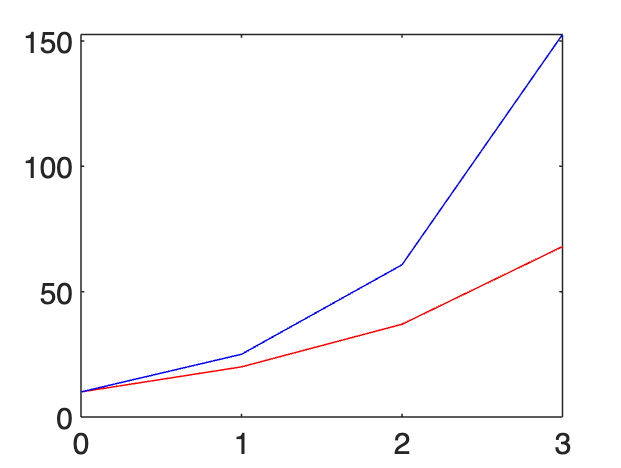


% inside for we need to calculate the error
for i=1:length(x)-1
    y(i+1)=y(i)+h*m(x(i),y(i));

    y_exacto = yexact(x(i+1));
    error_rel(i+1) = abs((y_exacto - y(i+1)) / y_exacto);
end

plot(x,y, 'r')
hold on
plot(x,yexact(x), 'b')
hold off